# Camera Calibration of my smartphone camera

The Zhang calibration procedure is performed here on a set of images taken with my smartphone to calibrate its camera. The images are in the folder 'my_images' and are 1280x960 pixel images of a 30 mm square, 8x6 vertices checkerboard. The procedure is the same as the one reporte in the file 'Calibration.mlx', apart from minor differences.

## Loading images

The images are saved with the same format of the images provided in the folder "images". The only difference is that the checkerboard is smaller, hence the number of correspondences is smaller with respect to the images providedin the folder 'images'; however, since the correspondences are 48, they are enough to provide reliable homogrpahies.

clear imageData
id = 'vision:calibrate:boardShouldBeAsymmetric';
warning('off',id)

iimage = [1 4 7 10]; %indices of the images to be processed

for ii=1:length(iimage)
    imageFileName = fullfile('my_images',['Image' num2str(iimage(ii)) '.tif']);
    I = imread(imageFileName);
    I = rgb2gray(I);
    imageData(ii).I = I;
    imageData(ii).XYpixel = detectCheckerboardPoints(imageData(ii).I);
end

## Establishing correspondances

squaresize = 30; %mm

for ii=1:length(iimage)
    %figure
    %imshow(imageData(ii).I, 'InitialMagnification',300)

    XYpixel=imageData(ii).XYpixel;
    clear Xmm Ymm;
    for jj=1:length(XYpixel)
        [row,col] = ind2sub([6,8],jj); % linear index to row,col
        
        Xmm = (col-1)*squaresize;
        Ymm = (row-1)*squaresize;

        imageData(ii).XYmm(jj,:)=[Xmm,Ymm];

        %hndtxt=text(XYpixel(jj,1), XYpixel(jj,2), num2str([Xmm Ymm]));
        %set(hndtxt, 'FontSize', 14, 'color', [1 mod(row,2)*mod(col,2) 0]);
    end
end

## Estimating homographies

for ii = 1:length(iimage)
    XYpixel=imageData(ii).XYpixel;
    XYmm=imageData(ii).XYmm;
    A=[];
    b=[];

    for jj=1:length(XYpixel)

        Xpixel = XYpixel(jj,1); % u
        Ypixel = XYpixel(jj,2); % v
        Xmm = XYmm(jj,1);       % x
        Ymm = XYmm(jj,2);       % y

        m = [Xmm; Ymm; 1]; 
        O = [0;0;0];
        A = [A;...
             m' O' -Xpixel*m'; ...
             O' m' -Ypixel*m'];
        b = [b;...
             0;
             0];
    end
    [~,~,V] = svd(A);
    h=V(:,end); 
    imageData(ii).H = reshape(h, [3 3])';    
end

## Zhang calibration procedure

V = [];

for ii=1:length(iimage)
    H = imageData(ii).H; 

    v12 = [H(1,1)*H(1,2); ...
           H(1,1)*H(2,2) + H(2,1)*H(1,2); ... 
           H(2,1)*H(2,2); ...
           H(3,1)*H(1,2) + H(1,1)*H(3,2); ...
           H(3,1)*H(2,2) + H(2,1)*H(3,2); ...
           H(3,1)*H(3,2)];

    v11 = [H(1,1)*H(1,1); ...
           H(1,1)*H(2,1) + H(2,1)*H(1,1); ... 
           H(2,1)*H(2,1); ...
           H(3,1)*H(1,1) + H(1,1)*H(3,1); ... 
           H(3,1)*H(2,1) + H(2,1)*H(3,1); ...
           H(3,1)*H(3,1)];

    v22 = [H(1,2)*H(1,2); ...
           H(1,2)*H(2,2) + H(2,2)*H(1,2); ... 
           H(2,2)*H(2,2); ...
           H(3,2)*H(1,2) + H(1,2)*H(3,2); ... 
           H(3,2)*H(2,2) + H(2,2)*H(3,2); ...
           H(3,2)*H(3,2)];

    V = [V; ...
         v12'; ...
         (v11-v22)'];
end
[U,E,S] = svd(V);
b = S(:,end);

B = [b(1) b(2) b(4); ...
     b(2) b(3) b(5); ...
     b(4) b(5) b(6)];

d = eig(B);
isposdef = all(d > 0);
if isposdef == false
    B = -B;
end

% Computing the intrinsics K 
R = chol(B); 
L = R';      
K = inv(L'); 
K = K/K(3,3);

% Computing the extrinsics and P 
for ii=1:length(iimage)
    H = imageData(ii).H; 
    h1  = H(:,1);
    h2 = H(:,2);
    h3 = H(:,3);
    lambda = 1/norm(K\h1); 
    r1 = lambda*(K\h1);
    r2 = lambda*(K\h2);
    r3 = cross(r1,r2);
    t = lambda*(K\h3);
    P = K*[r1 r2 r3 t];
    imageData(ii).R = [r1 r2 r3];
    imageData(ii).t = t;
    imageData(ii).P = P;
end


The estimated intrinsic parameters are:

disp(K)

   1.0e+03 *

    1.0384    0.0003    0.4589
         0    1.0375    0.5936
         0         0    0.0010



## Reprojection error

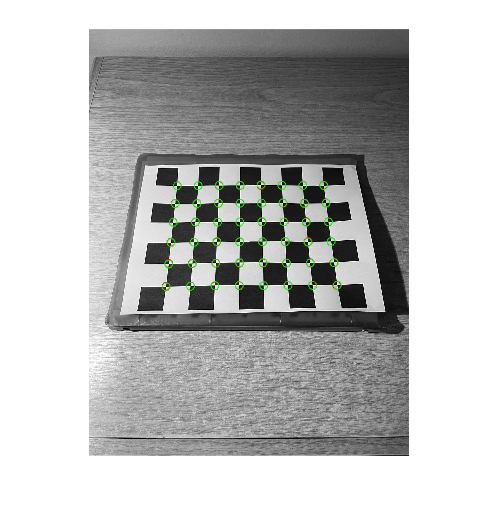

firstImage = imageData(1); 
XYmm    = firstImage.XYmm;
XYpixel = firstImage.XYpixel;
P       = firstImage.P;

figure
imshow(firstImage.I, 'InitialMagnification', 300)
hold on

tot_proj_error = 0;
for ii= 1:length(XYmm)
    % homogenous coordinates
    homog_real_world = [XYmm(ii,1); ... 
                        XYmm(ii,2); ...
                        0; ...
                        1];
    % projections
    proj_homographies  = P * homog_real_world; 
    projections = [proj_homographies(1)/proj_homographies(3); ...
                   proj_homographies(2)/proj_homographies(3);];

    % summing up the reprojection errors for every point in the checkerboard
    tot_proj_error = tot_proj_error + (projections(1)-XYpixel(ii,1))^2 + (projections(2)-XYpixel(ii,2))^2;

    plot(projections(1), projections(2), 'ro')
    plot(XYpixel(ii,1), XYpixel(ii,2), 'go')
end

disp(tot_proj_error)

   50.1778



## Superimposing cylinder

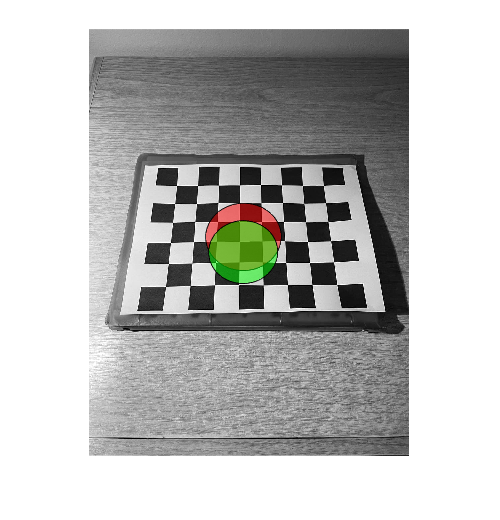

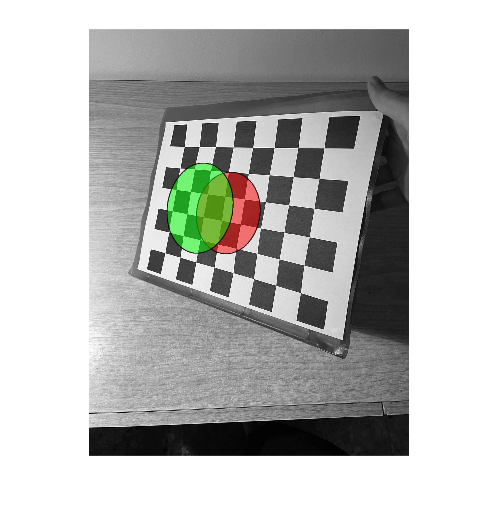

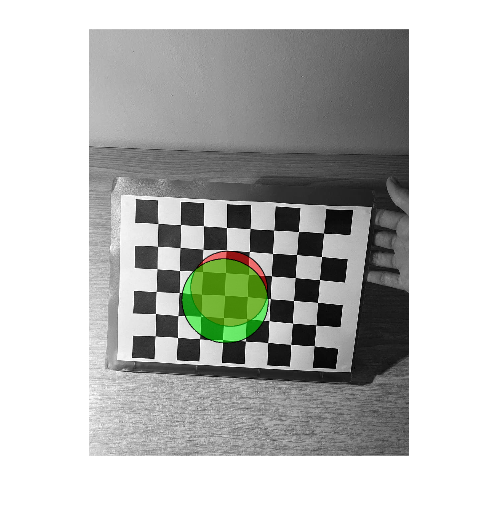

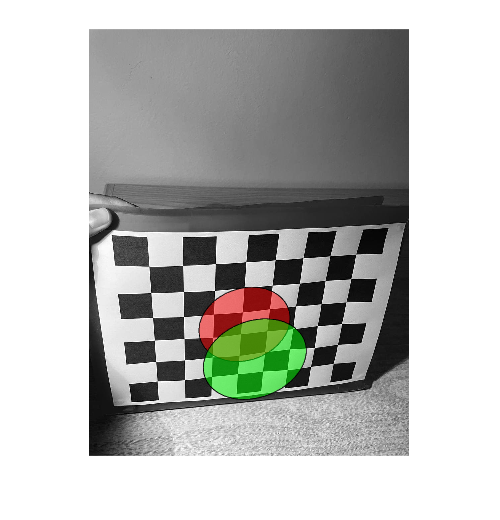

for ii=1:length(iimage)
    figure
    imshow(imageData(ii).I, 'InitialMagnification',200)
    hold on

    centerX = 95; 
    centerY = 80;                  
    radius  = 50;
    theta = 0:pi/50:2*pi;
    xunit = radius * cos(theta) + centerX;   
    yunit = radius * sin(theta) + centerY;

    homogeneous = [xunit; yunit; zeros(1,length(xunit)); ones(1,length(xunit))]; 
    proj_hom = imageData(ii).P*homogeneous; 
    proj = [ proj_hom(1,:)./proj_hom(3,:); ... 
             proj_hom(2,:)./proj_hom(3,:)];    
    fill(proj(1,:), proj(2,:), 'r','FaceAlpha',0.5);

    h = 50;
    homogeneous2 = [xunit; yunit; h*ones(1,length(xunit)); ones(1,length(xunit))]; 
    proj_hom2 = imageData(ii).P*homogeneous2; 
    proj2 = [ proj_hom2(1,:)./proj_hom2(3,:); ... 
             proj_hom2(2,:)./proj_hom2(3,:)];    
    fill(proj2(1,:), proj2(2,:), 'g','FaceAlpha',0.5);
    pause(1)
    hold off
end